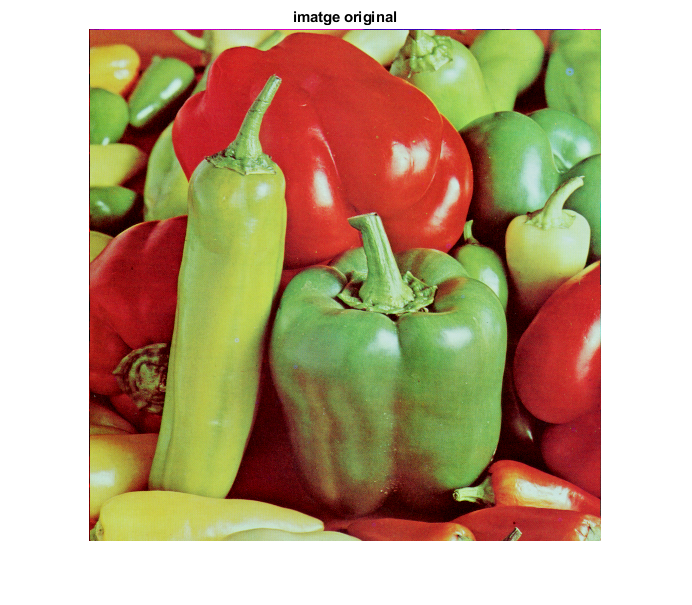

im=imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure,imshow(im),title('imatge original')


% la segmentarem per color. Treballarem en l'espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);

vect=reshape(hs,MAXFILA*MAXCOL,2);
[m,n] = size(vect);
nClusters = 3;
maxIt = 50;
vectCents = zeros(nClusters,1,'double');
vectDist = zeros(m,nClusters+2);
for i=1:nClusters
    aux = rand;
    vectCents(i) = rand * m;
end

for k = 1:maxIt
    
    for i = 1:m
        for j = nClusters
            vectDist(i,j) = (vect(i,:) - vectCents(j,:));
        end
        
    end
end
